## Cold plate requirements and operating conditions

The cold plate has to carry away a heat load of a maximum of 2kW. The working fluid is water. The desired maximum temperature at the cooling plate inlet is 25°C and the outlet temperature should not exceed 20°C. The coolant loop is assumed to operate at a pressure of 2 bar. The device temperature should not exceed 50°C. 

#### Operating conditions

QDiss           = 2000;         % (W) Heat load
deltaTCoolant   = 5;            % (°C) Maximum temperature rise allowed
TCoolantIn      = 25;           % (°C) Assumed coolant inlet temperature
TCoolantOutMax  = 30;           % (°C) Maximum coolant outlet temperature
TSurfaceMax     = 50;           % (°C) Maximum device temperature
TAmbient        = 20;           % (°C) Ambient temperature
pLoop           = 2;            % (bar) Pressure in coolant loop

#### Water properties at 25°C

cpCoolant       = 4180.74;      % (J/(kg*K)) heat cpacity
rhoCoolant      = 997.137;      % (kg/m^3) density
muCoolant       = 8.89995e-4;   % Pa·s
kCoolant        = 0.607;        % W/(m*K)
PrCoolant       = 6.134;        % (1) Prandtl number

#### Required flow rate

The required steady-state flow rate to keep the outlet temperature at a maximum of 30°C with the assumed inlet temperature is determined using:


$$Q_{\mathrm{Diss}} =\left(T_{\mathrm{cp},\mathrm{out}} -T_{\mathrm{cp},\mathrm{in}} \right)*{\dot{m} }_{\mathrm{water}} *c_{p,\mathrm{water}}$$


mDot    = QDot/(cpCoolant*deltaTCoolant); % (kg/s) Mass flow rate
VDot    = mDot/rhoCoolant;                % (m^3/s) Volumetric flow rate
VDotLPM = mDot/rhoCoolant*1000*60;        % (l/min) Volumetric flow rate

#### Testing in a Simscape model

To test this in a simulation a simple model is build

open_system("example_TCoolantOut")

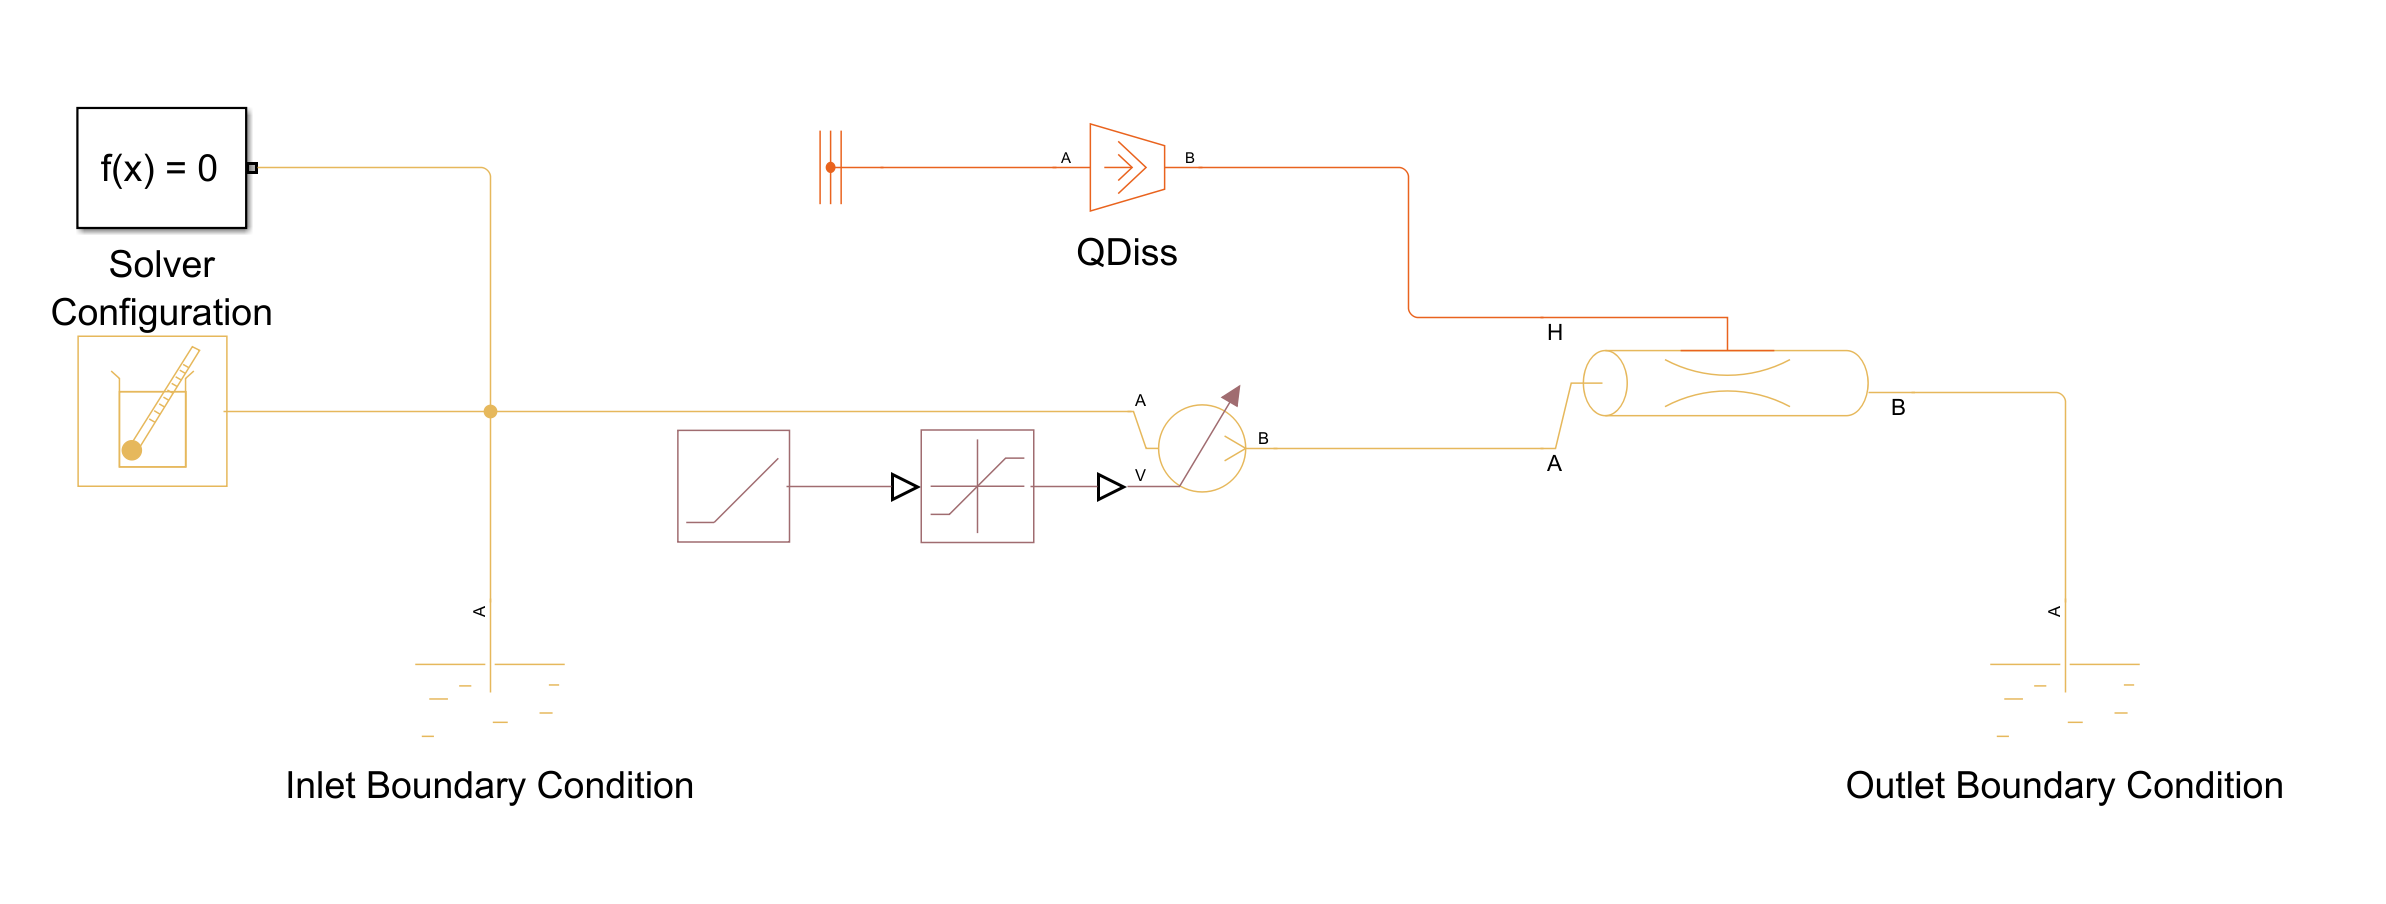

Two Reservoirs act as as inlet and outlet boundary conditions. Since we are only looking at results after the simulation has reached steady-state and are at this point not looking at pressure losses, we leave the pipe geometry parameters at the default values. The  flow rate is created using a Flow Rate Source, we are starting from resting fluid and ramping up to the desired flow rate. We leave the model running for a long enough simulation time to reach steady state. An look at the result at the final result.

simInp = Simulink.SimulationInput("example_TCoolantOut");
simInp = simInp.setModelParameter("StopTime","7200");

simOut = sim(simInp);

Next, we'll extract resuts from the Simscape logging object. For the pipe block we can extract values for the ports (**A** and **B**) and since the block also has a internal fluid volume the node **T_I** will also be visible in the Simscape logging object. In the example we imposed a positive flow rate, meaning the flow will go from port A to port B in the pipe, therefore the temperature at port B will be the same as at port T_I. This is due to the [Upwinding Numerical Scheme](https://www.mathworks.com/help/releases/R2025a/hydro/ug/simscape-fluids-numerical-scheme.html). 